## Project 1 Code

% come up with bottom line
% come up with top line
% use matrix methods on both
% find where bottom line intersects the actual line as it starts to go up
% use the same time from bottom line on the top line (max temp)
% average minimum temp/max temp
% find the time when the actual graph equals average (t = t_avg)
% then plug that time into the upper line
% once you have the true maximum temperature, use calorimetry equation to
% find specific heat

% t0 is bottom temperature (calc)
% t1 is temperature of water bath
% t2 is final temperature of calorimeter and sample (calc)

% at some point they turn the water bath off, so be careful finding a data
% point for water bath

data = readtable("SampleD");
time = data.Var2;
t1 = data.Var3;
t1_error = std(t1);
t2 = data.Var6;
t2_error = std(t2);
temp = (t1+t2)/2; % uncertainty in this
% using general method
temp_error = (((1/2) .* t1_error).^2 + ((1/2) .* t2_error).^2).^(1/2);
T_Water = data.Var4;

plot(time,temp,"Linewidth",2)
hold on

Using matrix methods to fit a line to pre-sample addition data

% bottom line calculation
% assuming all data points have the same uncertainty
timeb = time(1:425,1); % determined by finding where temperature starts to increase
tempb = temp(1:425,1);
% H matrix (partial derivatives)
H_b = [ones(length(tempb),1),timeb];
% least squares 
delta_temp_b (1:length(tempb)) = temp_error; % error from averaging
Diagonal_b = 1 ./ (delta_temp_b .* delta_temp_b);
W_b = diag(Diagonal_b); % weighting matrix

X_hat_b = ((H_b' * W_b * H_b)^-1) * H_b' * W_b * tempb;
A_b = X_hat_b(1); % y intercept
B_b = X_hat_b(2); % slope of bottom fit line
% finding uncertainty in data

% Two lines below are just for finding error in temp
% Deviation_b = tempb - (A_b + B_b.*timeb);
% Sigma_y_bottom = sqrt((1/(length(tempb)-length(X_hat_b))) * sum(Deviation_b .* Deviation_b));

% using weighting matrix and P matrix to find uncertainty in each point
P_b = (H_b' * W_b * H_b)^-1; % error covariance matrix
A_b_error = sqrt(P_b(1,1)); % error in A values
B_b_error = sqrt(P_b(2,2)); % error in B values
Sigma_q_bottom = (P_b(1,1) + (timeb.^2 .* P_b(2,2))).^(1/2);

% fit line
bottom_fit = A_b + B_b .* timeb;

Using matrix methods to fit a line to post-sample addition data

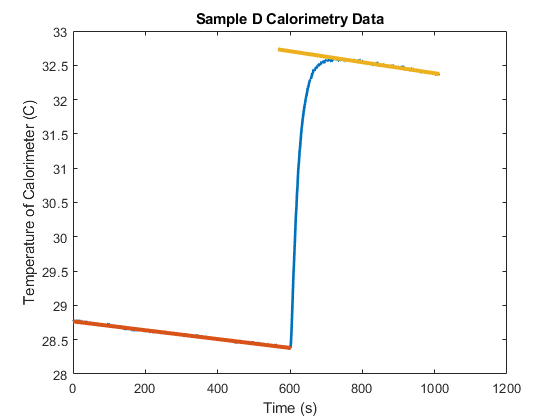

% top line calculation
% assuming all data points have the same uncertainty
tmaxTemp = time(temp==max(temp)); % determines starting point for top fit line
timet = time(515:end,1); % determined graphically from max value
tempt = temp(515:end,1);
% H matrix (partial derivatives)
H_t = [ones(length(tempt),1),timet];

% least squares
delta_temp_t (1:length(tempt)) = temp_error; % error from averaging
Diagonal_t = 1 ./ (delta_temp_t .* delta_temp_t);
W_t = diag(Diagonal_t); % uncertainty weight matrix

X_hat_t = ((H_t' * W_t * H_t)^-1) * H_t' * W_t * tempt;
A_t = X_hat_t(1); % y intercept of top fit line
B_t = X_hat_t(2); % slope of top fit line
% finding uncertainty in deta

% Two lines below are just for finding error in temp
% Deviation_t = tempt - (A_t + B_t.*timet);
% Sigma_y_top = sqrt((1/(length(tempt)-length(X_hat_t))) * sum(Deviation_t .* Deviation_t));

% using weighting matrix and P matrix to find uncertainty in each point
P_t = (H_t' * W_t * H_t)^-1; % error covariance matrix
A_t_error = sqrt(P_t(1,1)); % error in A
B_t_error = sqrt(P_t(2,2)); % error in B
Sigma_q_top = (P_t(1,1) + (timet.^2 .* P_t(2,2))).^(1/2);

% fit line
top_fit = A_t + B_t .* time(400:end,1); % extrapolate top fit line to domain of bottom fit line
plot(timeb,bottom_fit,"LineWidth",3)
plot(time(400:end,1),top_fit,"Linewidth",3)
title("Sample D Calorimetry Data")
xlabel("Time (s)")
ylabel("Temperature of Calorimeter (C)")
hold off

With the lines of best fit fixed, it's time to find the times and temperatures desired

sampleAddTime = time(bottom_fit==min(bottom_fit)); % time when slope of temp/time graph skyrockets
sampleAddTemp = min(bottom_fit); % temperature at that point

AddTempError = sqrt(A_b_error^2 + B_b_error^2 .* sampleAddTime^2); % uncertainty in straight line fit

maxTheoTemp = A_t + B_t .* sampleAddTime; % holder, used to calculate more accurate max temp
avgTemps = (maxTheoTemp + sampleAddTemp) ./2; % average of pre-sample temp and max temp

% finding the closest index that matches this temperature
[~,ind] = min(abs(temp-avgTemps));
maxTime = time(ind,1); % time when sample is at maximum temperature
maxTemp = A_t + B_t .* maxTime; % temperature at that time
MaxTempError = sqrt(A_t_error^2 + B_t_error^2 .* maxTime^2); % uncertainty in straight line fit

% finding a good value for water temp, and its uncertainty
waterHolder = T_Water(1:448,1); % vector of water values
waterTemp = mean(waterHolder); % 
waterError = std(waterHolder)/sqrt(length(waterHolder));

Specific Heat Calculation

m_c = 0.51 * 1000; % g
m_s = 88.897; % g
C_cav = .895; % J/(gC)
T_2 = maxTemp; % C
T_2_error = MaxTempError

T_2_error = 1.2285

T_1 = waterTemp; % C
T_1_error = waterError

T_1_error = 0.0033

T_0 = sampleAddTemp; % C
T_0_error = AddTempError

T_0_error = 0.2573


C_sAv = (m_c * C_cav * (T_2 - T_0))/(m_s * (T_1-T_2))

C_sAv = 0.3605

% IMPORTANT
% masses also have uncertainty (+- 5 on the last digit (39.306 +- .005))

% using general method to propogate uncertainty
dt_0 = ((-m_c*C_cav)/m_s)/(T_1-T_2);
dt_1 = (((-m_c*C_cav)/m_s)*(T_2-T_1))/(T_1-T_2)^2;
dt_2 = (((-m_c*C_cav)/m_s)*(T_0-T_1))/(T_1-T_2)^2;
error = sqrt((dt_0 * T_0_error)^2 + (dt_1 * T_1_error)^2 + (dt_2 * T_2_error)^2)

error = 0.1120


disp("Specific heat of Sample D: " + round(C_sAv,2) + " +- " + round(error,2))

Specific heat of Sample D: 0.36 +- 0.11


Comparing specific heat values

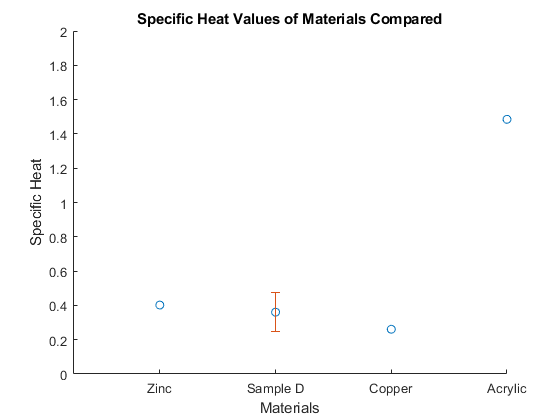

C_Acrylic = 1.485;
C_Zinc = 0.402;
C_Copper = 0.261;
samples = [C_Zinc C_sAv C_Copper C_Acrylic];
scatter(linspace(0.2,1,4),samples)
hold on
title("Specific Heat Values of Materials Compared")
xlim([0 1])
ylim([0 2])
xticks(linspace(0.2,1,4))
xlabel("Materials")
ylabel("Specific Heat")
xticklabels(["Zinc","Sample D","Copper","Acrylic"])
errorbar(0.4667,C_sAv,error)
hold off